# Simulate Physical Model

## Open Model

modelName = 'simpleHelicopter_toReduce';
open_system(modelName)

Enable or disable network trainning:

train = true;

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

ascendScenarioVector = 2e3:1e3:5e3;
ascendDescentScenarioVector = [2e3:1e3:5e3 5e3:-1e3:2.5e3];
referenceHeatStates = {
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+155],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+305],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+605],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+655], simStopTime}, ...
                    {ascendDescentScenarioVector,simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+150],simStopTime}, ...                      
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+300],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+450], simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+600],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

Unrecognized function or variable 'scenarioDir'.

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)
clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};

    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

--------------------------------------------


ix = 1

ans =         2000        2000        3450        3450        4450        4450        5450        5450        5450        5450        4450        4450        3450        3450


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

--------------------------------------------


ix = 2

ans =         2000        2000        3600        3600        4600        4600        5600        5600        5600        5600        4600        4600        3600        3600


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

--------------------------------------------


ix = 3

ans =         2000        2000        3650        3650        4650        4650        5650        5650        5650        5650        4650        4650        3650        3650


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

--------------------------------------------


ix = 4

ans =         2000        2000        3155        3155        4155        4155        5155        5155


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 5

ans =         2000        2000        3305        3305        4305        4305        5305        5305


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 6

ans =         2000        2000        3455        3455        4455        4455        5455        5455


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 7

ans =         2000        2000        3455        3455        4455        4455        5455        5455


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 8

ans =         2000        2000        3605        3605        4605        4605        5605        5605


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 9

ans =         2000        2000        3655        3655        4655        4655        5655        5655


ans =      0    80   100   180   200   280   300   380


ans = '375'

--------------------------------------------


ix = 10

ans =         2000        2000        3000        3000        4000        4000        5000        5000        5000        5000        4000        4000        3000        3000


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

--------------------------------------------


ix = 11

ans =         2000        2000        3150        3150        4150        4150        5150        5150        5150        5150        4150        4150        3150        3150


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

--------------------------------------------


ix = 12

ans =         2000        2000        3300        3300        4300        4300        5300        5300        5300        5300        4300        4300        3300        3300


ans =      0    40    50    90   100   140   150   190   200   240   250   290   300   340


ans = '335'

## Simulate

Simulate in parallel and save the results

out = parsim(simIn,'ShowSimulationManager','on');

[07-Nov-2023 11:49:36] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
[07-Nov-2023 11:50:02] Starting Simulink on parallel workers...
[07-Nov-2023 11:50:15] Loading project on parallel workers...
[07-Nov-2023 11:50:15] Configuring simulation cache folder on parallel workers...
[07-Nov-2023 11:50:28] Loading model on parallel workers...
[07-Nov-2023 11:50:33] Running simulations...
[07-Nov-2023 11:56:30] Cleaning up parallel workers...


save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample simulation data

Extract data table from simulation results

for ix = 1:length(out)
    resultsTable{ix} = out(ix).logsout.extractTimetable;
end

Resample the data in seconds using [anonymous functions](https://uk.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) and [cellfun](https://uk.mathworks.com/help/matlab/ref/cellfun.html):

sampleTime = 0.1;
timeStep = out(1).tout(2)-out(1).tout(1);
batchDownSample = @(x) downsample(x,sampleTime/timeStep);
resampledData = cellfun(batchDownSample, resultsTable,'UniformOutput', false);

Reorder signals using [movevars](https://uk.mathworks.com/help/matlab/ref/table.movevars.html): 

commandSignals = {'Altitude', 'Qin'};
resampledData = cellfun(@(x) movevars(x,commandSignals{1},'Before',1), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,commandSignals{2},'Before',2), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'T3','After',8), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'P2','After',8), resampledData,'UniformOutput', false);

sigNames = resampledData{1}.Properties.VariableNames;

## Visualize resampled data

Visualize table data with [stackedplot](https://uk.mathworks.com/help/matlab/ref/stackedplot.html):

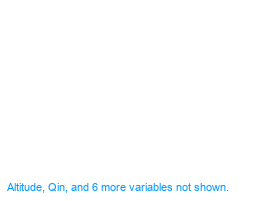

figure
stackedplot(resampledData)

## Normalize data

Concatenate the data using the [vertcat](https://uk.mathworks.com/help/matlab/ref/double.vertcat.html?searchHighlight=Vertcat&s_tid=doc_srchtitle) function:

concatDataTrain = vertcat(resampledData{:});

calculate the mean and standard deviation of the simulation data, with [mean](https://uk.mathworks.com/help/matlab/ref/mean.html) and [std](https://uk.mathworks.com/help/matlab/ref/std.html) functions

meanTrain = mean(concatDataTrain);
stdTrain = std(concatDataTrain);

save the results and clear the concatenated data

clear concatDataTrain
save meanTrain meanTrain
save stdTrain stdTrain

Apply gaussian normalization to the entire set of data.

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain, stdTrain), resampledData, 'UniformOutput', false);

## Prepare data for training

Define the normalized inputs and the expected responses as seen below:

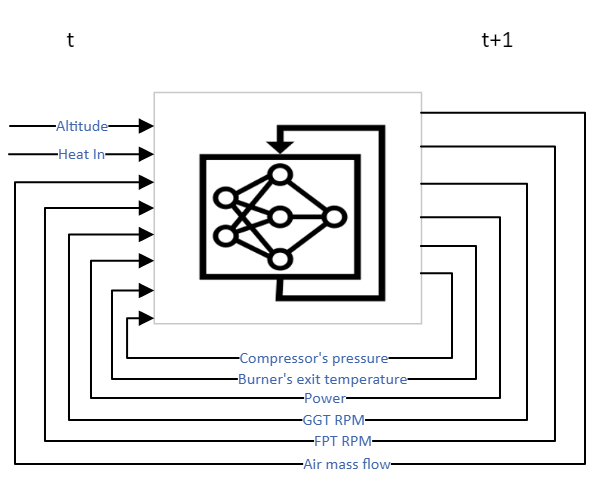

outStartIdx = length(commandSignals)+1;
inOut = @(x)[{x(1:end-1,:)} {x(2:end, outStartIdx:end)}];

aux = cellfun(inOut,dataTrainNormComp,'UniformOutput', false);

for ix=1:numel(dataTrainNormComp)
    inputTrain{ix} = table2array(aux{ix}{1});
    responseTrain{ix} = table2array(aux{ix}{2});
end
clear aux

# Train a Neural Network

## Define the inputs/outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
numHiddenUnits = 150;
dropoutProbability = 0.2;

## Network architecture

Choose [lstmLayer](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html) for timeseries prediction 

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    ];

## Training options

Define solver, specify learning rate and trainnig epochs

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the network

Train LSTM network using the [trainnet](https://uk.mathworks.com/help/deeplearning/ref/trainnet.html) function:

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:02         0.01         0.84695
           50       50       00:00:55         0.01       0.0068356
          100      100       00:01:42         0.01       0.0037959
          150      150       00:02:31         0.01       0.0032052
          200      200       00:03:20         0.01       0.0029328
          250      250       00:04:09        0.001       0.0028986
          300      300       00:04:57        0.001       0.0029239
          350      350       00:05:46        0.001       0.0029118
          400      400       00:06:34        0.001       0.0028828
          450      450       00:07:24       0.0001       0.0028885
          500      500       00:08:16       0.0001       0.0028731
Training stopped: Max epochs completed


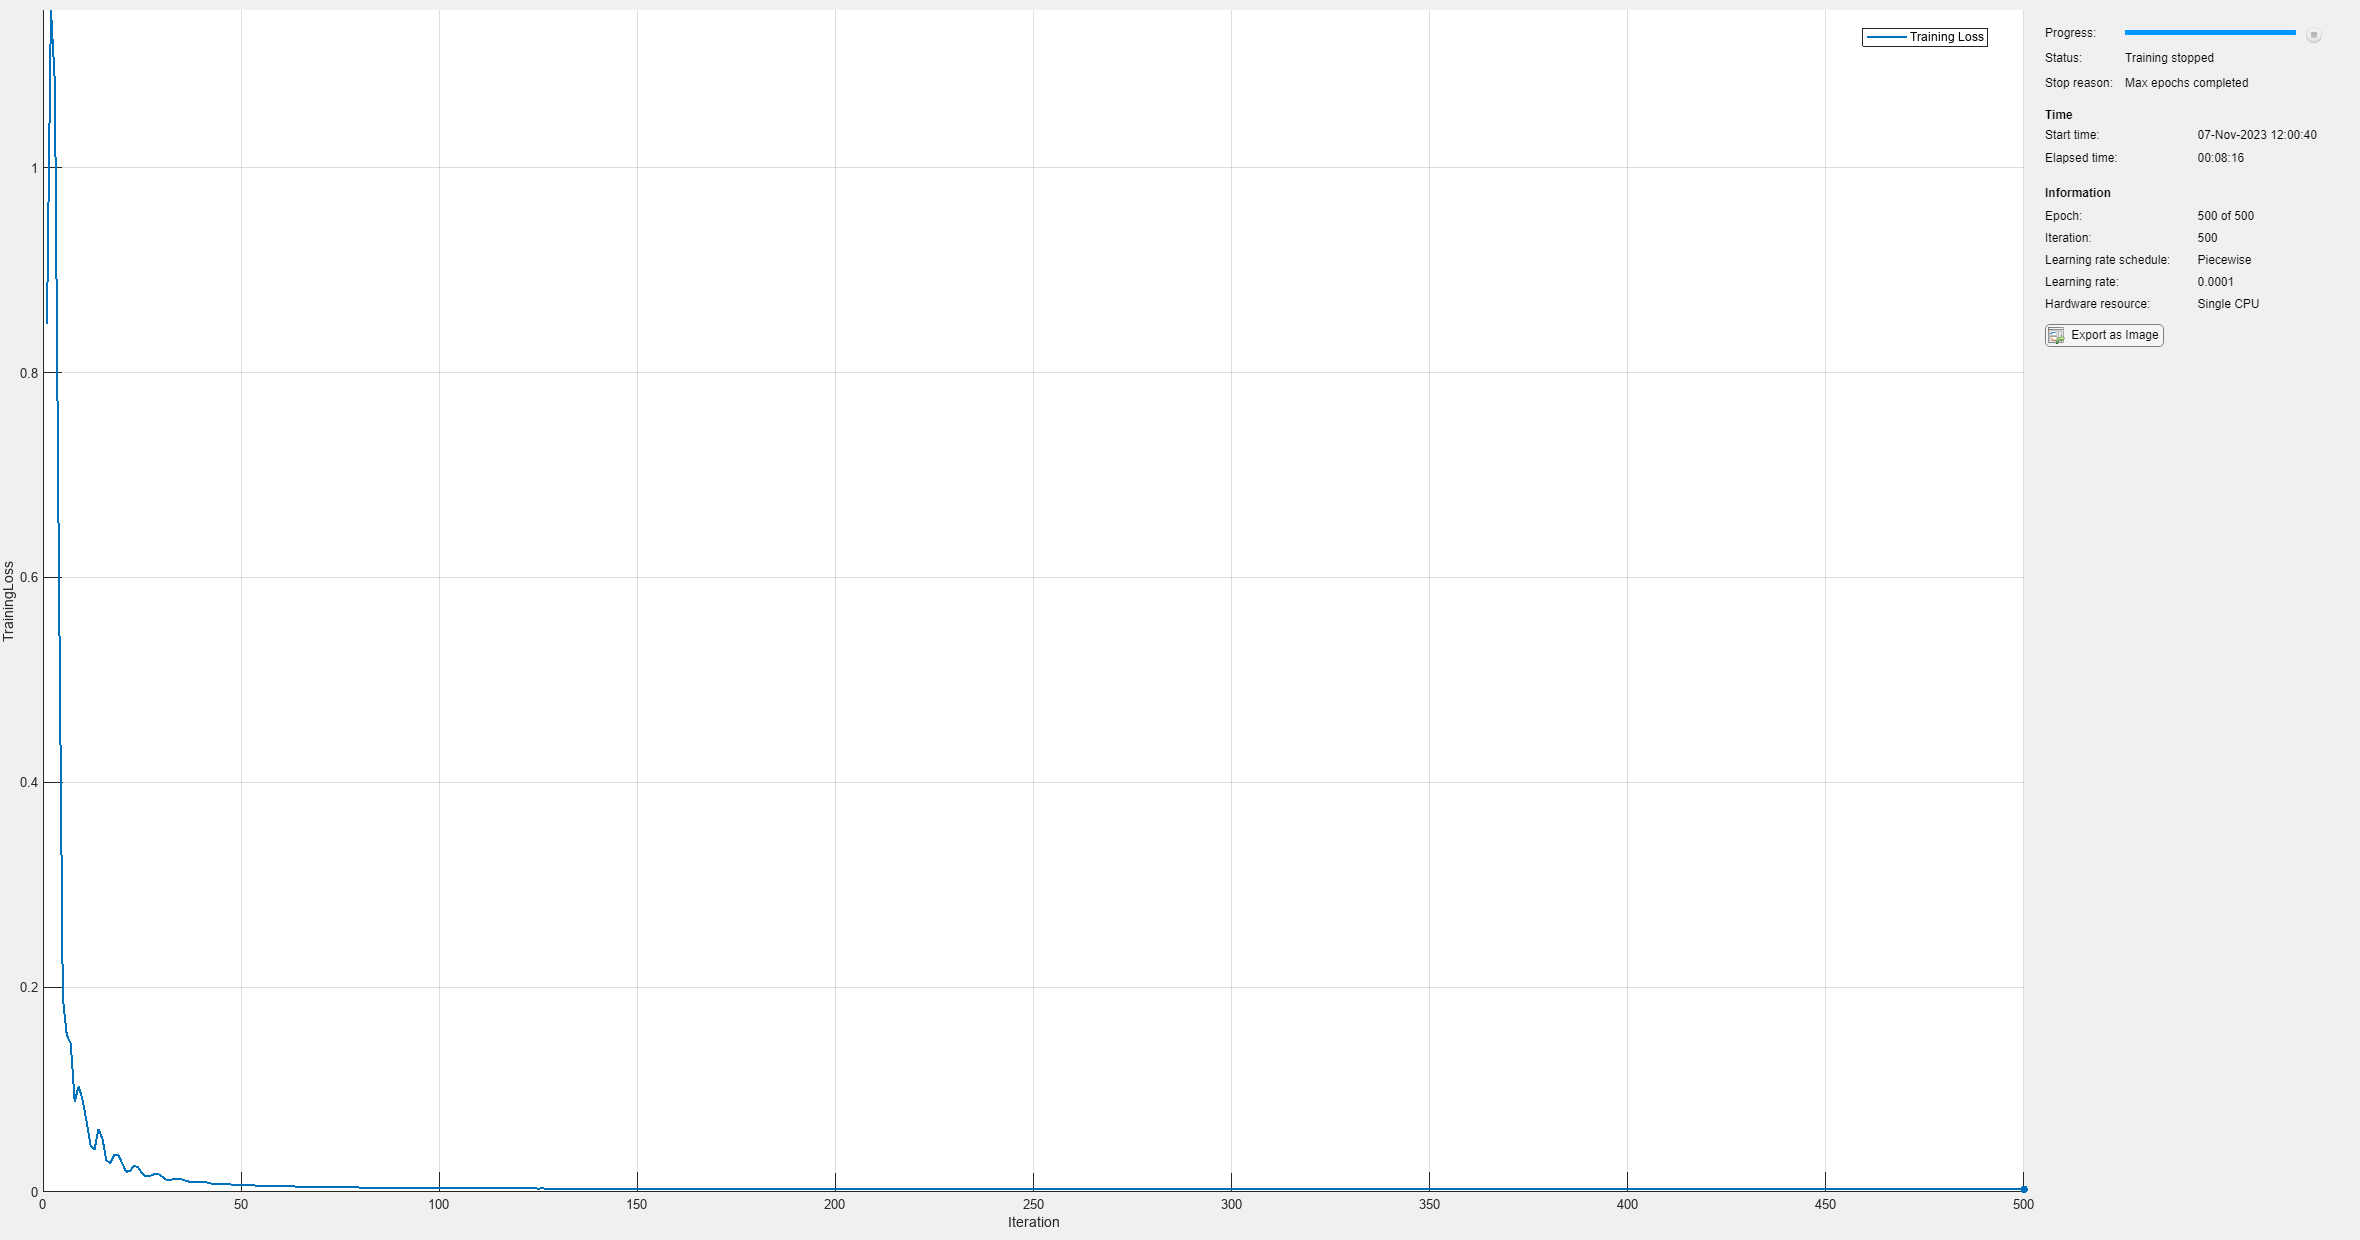

if train
    [net, ~] = trainnet(inputTrain,responseTrain,layers,'mean-squared-error',opts);
    net = resetState(net);
    save("turboshaftEngine\Models\Components\turboShaftEngineLSTM_ROM\turboshaft_ROM_v5.mat","net")
end

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

reducedModel = 'simpleHelicopter_ROM';
open_system(reducedModel)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is on a scenario that has not been included in the trainning.

mode = 'Custom';

## Simulate the ROM

set_param([reducedModel,'/HeatIn'],'LabelModeActivechoice', mode)
romSim = sim(reducedModel);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

Simulate the physical model with the same simulation scenario:

referenceModel = 'simpleHelicopter_reference';
open_system(referenceModel)
set_param([referenceModel,'/HeatIn'],'LabelModeActivechoice', mode)
refSim = sim(referenceModel);
refRunID = Simulink.sdi.Run.getLatest;

## Test in Simulation Data Inspector

Define the acceptable absolute and relative tolerances

relTol = 2.5e-2;
absTol = 6;

Launch comparison on the Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol);
Simulink.sdi.view

## Performance comparison

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo;
ref.init = refSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
ref.execution = refSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
ref.total = refSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
baseline = [ref.init ref.execution ref.total];

The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo;
rom.init = romSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
rom.execution = romSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
rom.total = romSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
reduced = [rom.init rom.execution rom.total];

Compare performance:

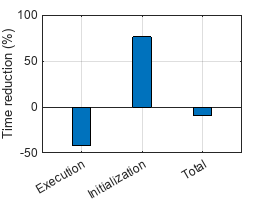

categories = categorical({'Initialization','Execution','Total'});
timereduction = (baseline-reduced)./baseline.*100;
bar(categories, timereduction, 0.3)
ylabel('Time reduction (%)')
grid('on')

# Real-Time Simulation

Use Simulink Real-Time to simulate the model in real time:

open_system('simpleHelicopter_ROM_realTime')

 Let's take-off !

# DRAFT

## Prepare Data For Training

trainPercentage = 0.8; % the percentage of the data that they will be used for training
                       % the rest will be used for test
[dataTrain, dataTest, meanTrain, stdTrain] = prepareDataNormalization(resampledData, trainPercentage);
save meanTrain meanTrain
save stdTrain stdTrain



*PH: Envoyer des donnes*

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

## Compare with Simulink Test

import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions

Create a test case:

testCase = TestCase.forInteractiveUse;    

Set the accepted relative and absolute tolerance:

relTol = 2e-2;
absTol = 6;

Compare different signals between ROM LSTM model and original model.

for ix=1:length(sigNames)
    basselineSig = refSim.logsout.getElement(sigNames{ix});
    romSig = romSim.logsout.getElement(sigNames{ix});
    testCase.verifyThat(romSig,MatchesSignal(basselineSig,'RelTol',relTol))
end